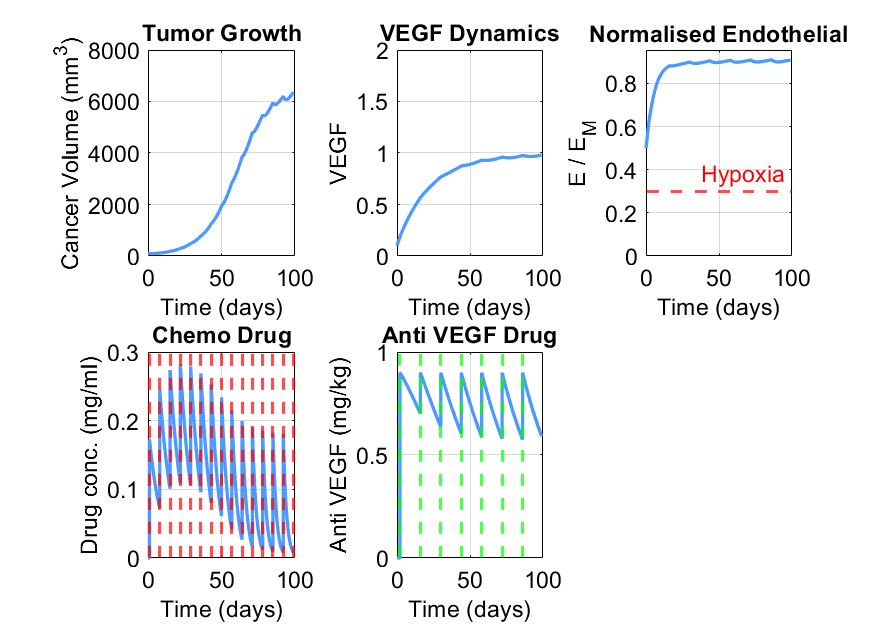

Figure saved to: C:\Users\31628\Desktop\tumor_model_plot.png


%% TumorGrowthModel.m
% -------------------------------------------------------------------------
% Tumor Growth Model with Gradual Drug Effect and Capped Drug Concentrations
%
% Author : Nikoletta, Marty, Greta, Evie
% Created: 2025‑07‑02
% BBS2061 Project group 1c systems biology
% License: MIT 
% -------------------------------------------------------------------------
% DESCRIPTION
%   This MATLAB script simulates the coupled dynamics of cancer cells (C),
%   chemotherapy drug (D), endothelial cells (E), vascular endothelial growth
%   factor (VEGF, V) and an anti‑VEGF agent (A). Drug concentrations are
%   prevented from exceeding physiologically plausible values by capping them
%   to D_max and A_max immediately after each bolus injection.
%
%   The ODE system is integrated piece‑wise between injection events using
%   ODE15s. At each event time we (i) add the bolus dose, (ii) apply the
%   caps, and (iii) continue integration until the next event.
%
% QUICK START
%   1.  Clone / download this repository.
%   2.  Open MATLAB in the repository folder.
%   3.  Run this script:
%           >> TumorGrowthModel
%
% OUTPUT
%   • results/tumor_model_plot.png – diagnostic plot saved automatically.
%
% DEPENDENCIES
%   • MATLAB R2020a or newer (uses implicit solver ODE15s).
% -------------------------------------------------------------------------

%% 1. Simulation time --------------------------------------------------------
t0 = 0;           % start (days)

tf = 99;          % end   (days)

%% 2. Initial conditions  [ C ; D ;  E ;  V ;  A ] --------------------------
%                               (mm³) (mg/ml)  (—)   (—)  (mg/kg)
x0 = [100.0497;   ... % Cancer cells
      0;          ... % Chemo concentration (initially 0)
      0.5;        ... % Endothelial cells
      0.1;        ... % VEGF
      0];             % Anti‑VEGF

%% 3. Model parameters -------------------------------------------------------
params = struct(...
    'd_c', 0.2030, ...       % Cancer natural death rate (1/day)
    'b', 0.22, ...           % Drug efficacy
    'lambda_ce', 0.3579, ... % Cancer proliferation (1/day)
    'd_d', 0.12, ...         % Chemo clearance (1/day)
    'b_k', 6e-5, ...         % Drug binding rate (/day)
    'c_M', 1e4, ...          % Cancer carrying capacity (mm³)
    'E_thresh', 0.3, ...     % Hypoxia threshold (E/E_M)
    'lambda_e', 0.3, ...     % Endothelial proliferation (1/day)
    'E_M', 1.0, ...          % Endothelial carrying capacity (—)
    'd_e', 0.02, ...         % Endothelial death (1/day)
    'd_v', 0.024, ...        % VEGF decay (1/day)
    'd_b', 0.008, ...        % Anti‑VEGF clearance (1/day)
    'lambda_v0', 14.4, ...   % VEGF production when hypoxic (1/day)
    'k', 0.1, ...            % VEGF‑induced proliferation (1/day)
    'mu_Bk', 0.025, ...      % Anti‑VEGF binding clearance (/day)
    'V_M', 0.01, ...         % Michaelis constant for VEGF (—)
    ... % Chemo dosing
    'dose_amount', 0.173, ...                          % Chemo bolus (mg/ml)
    'dose_times',      [1 8 15 22 29 36 43 50 57 64 71 78 85 92 99], ...
    ... % Anti‑VEGF dosing
    'anti_dose_amount', 1, ...                         % Anti‑VEGF bolus (mg/kg)
    'anti_dose_times', [2 16 30 44 58 72 86], ...
    ... % Concentration caps
    'D_max', 2.5, ...         % Max chemo conc. (mg/ml)
    'A_max', 0.9 ...          % Max anti‑VEGF conc. (mg/kg)
);

% Pre‑compute chronological list of all injection events
all_events = unique([params.dose_times, params.anti_dose_times]);

%% 4. ODE integration setup --------------------------------------------------
options = odeset('Events', @(t,y) combinedEvents(t,y,params));
all_t = []; all_Y = [];

current_time = t0;
current_Y    = x0;
current_event_idx = 1;

%% 5. Piece‑wise integration -------------------------------------------------
while current_time < tf && current_event_idx <= numel(all_events)
    next_event = all_events(current_event_idx);
    t_span     = [current_time, next_event];

    % Integrate until the next scheduled injection
    [T, Y, te] = ode15s(@(t,y) Model_with_injections(t,y,params), t_span, current_Y, options);

    all_t = [all_t; T];        %#ok<AGROW>
    all_Y = [all_Y; Y];        %#ok<AGROW>

    % Update state at the event time --------------------------------------
    current_time = T(end);
    current_Y    = Y(end,:)' ;

    % Apply bolus doses and enforce concentration caps --------------------
    if ~isempty(te)
        if ismember(next_event, params.dose_times)
            current_Y(2) = min(current_Y(2) + params.dose_amount, params.D_max);
        end
        if ismember(next_event, params.anti_dose_times)
            current_Y(5) = min(current_Y(5) + params.anti_dose_amount, params.A_max);
        end
        current_event_idx = current_event_idx + 1;
    end
end

% Integrate the remainder of the simulation window (after last injection)
if current_time < tf
    [T, Y] = ode15s(@(t,y) Model_with_injections(t,y,params), [current_time tf], current_Y);
    all_t = [all_t; T];
    all_Y = [all_Y; Y];
end

T = all_t;  X = all_Y;  %#ok<NASGU>

%% 6. Diagnostics plot -------------------------------------------------------

figure('Color','w','Position',[100 100 1000 720]);

% Common styling
fontName  = 'Arial';
fontSize  = 14;
lineWidth = 2;
lightBlue = [0.3 0.6 1];
black     = [0 0 0];

% Tumor volume --------------------------------------------------------------
subplot(2,3,1);
plot(T, X(:,1), 'Color', lightBlue, 'LineWidth', lineWidth);
xlabel('Time (days)',          'FontName',fontName,'FontSize',fontSize);
ylabel('Cancer Volume (mm^3)','FontName',fontName,'FontSize',fontSize);
title('Tumor Growth','FontName',fontName,'FontSize',fontSize,'FontWeight','bold');
grid on; box on;
ylim([0 8000]);

% VEGF ----------------------------------------------------------------------
subplot(2,3,2);
plot(T, X(:,4), 'Color', lightBlue, 'LineWidth', lineWidth);
xlabel('Time (days)','FontName',fontName,'FontSize',fontSize);
ylabel('VEGF','FontName',fontName,'FontSize',fontSize);
title('VEGF Dynamics','FontName',fontName,'FontSize',fontSize,'FontWeight','bold');
grid on; box on;
ylim([0 2]);

% Endothelial cells (normalised) -------------------------------------------
subplot(2,3,3);
E_norm = X(:,3) ./ params.E_M;
plot(T, E_norm, 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
yline(params.E_thresh, '--r', 'Hypoxia', 'LineWidth', lineWidth);
hold off;
xlabel('Time (days)','FontName',fontName,'FontSize',fontSize);
ylabel('E / E_M','FontName',fontName,'FontSize',fontSize);
title('Normalised Endothelial','FontName',fontName,'FontSize',fontSize,'FontWeight','bold');
ylim([min(0, params.E_thresh - 0.05), max(E_norm)*1.05]);
grid on; box on;

% Chemotherapy concentration -------------------------------------------------
subplot(2,3,4);
plot(T, X(:,2), 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
arrayfun(@(t) xline(t, '--r', 'LineWidth', lineWidth), params.dose_times);
hold off;
xlabel('Time (days)','FontName',fontName,'FontSize',fontSize);
ylabel('Drug conc. (mg/ml)','FontName',fontName,'FontSize',fontSize);
title('Chemo Drug','FontName',fontName,'FontSize',fontSize,'FontWeight','bold');
grid on; box on;

% Anti‑VEGF concentration ----------------------------------------------------
subplot(2,3,5);
plot(T, X(:,5), 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
arrayfun(@(t) xline(t, '--g', 'LineWidth', lineWidth), params.anti_dose_times);
hold off;
xlabel('Time (days)','FontName',fontName,'FontSize',fontSize);
ylabel('Anti‑VEGF (mg/kg)','FontName',fontName,'FontSize',fontSize);
title('Anti‑VEGF Drug','FontName',fontName,'FontSize',fontSize,'FontWeight','bold');
grid on; box on;

% Apply font to all axes ----------------------------------------------------
set(findall(gcf,'Type','axes'),  'FontName',fontName,'FontSize',fontSize);
set(findall(gcf,'Type','text'),  'FontName',fontName,'FontSize',fontSize);

% Save figure to ./results ---------------------------------------------------
resultsDir = fullfile(pwd, 'results');
if ~exist(resultsDir, 'dir'); mkdir(resultsDir); end
filename   = fullfile(resultsDir, 'tumor_model_plot.png');
saveas(gcf, filename);
fprintf('Figure saved to %s\n', filename);

%% 7. Local functions --------------------------------------------------------


function dYdt = Model_with_injections(~, Y, params)
    % Unpack state variables
    C = Y(1); D = Y(2); E = Y(3); V = Y(4); A = Y(5);

    % Fraction of endothelial cells relative to carrying capacity
    E_frac  = E / params.E_M;
    hypoxic = E_frac < params.E_thresh;

    % Basal VEGF production to avoid zero values
    basal_lambda_v = 0.05;

    % Tumor dynamics
    dCdt = params.lambda_ce * E_frac * C * (1 - C/(params.c_M * (1 + E_frac))) ...
           - params.d_c * C - params.b * C * D;

    % Chemo drug dynamics
    dDdt = -params.d_d * D - params.b_k * C * D * E_frac;

    % Endothelial cell dynamics
    dEdt = params.lambda_e * (V/(V + params.V_M)) * E * (1 - E/params.E_M) ...
           - params.d_e * E + params.k * V * E * (1 - E/params.E_M) ...
           - params.mu_Bk * A * E;  % death induced by anti‑VEGF

    % VEGF dynamics
    dVdt = basal_lambda_v ...
           + (hypoxic * params.lambda_v0) * C * (1 - E_frac) ...
           - params.k * V * E * (1 - E_frac) ...
           - params.d_v * V ...
           - params.mu_Bk * V * A;

    % Anti‑VEGF dynamics
    dAdt = -params.d_b * A - params.mu_Bk * V * A;

    dYdt = [dCdt; dDdt; dEdt; dVdt; dAdt];
end

function [value, isterminal, direction] = combinedEvents(t, ~, params)
    % Trigger an event when 't' reaches any injection time
    value      = t - sort([params.dose_times, params.anti_dose_times]);
    isterminal = true(size(value)); % stop integration at event
    direction  = ones(size(value)); % detect zero from negative to positive
end
